## **Question 1**

- Consider the the Lorenz-63 model with the setting used in Project 1. The data assimilation problem is posed over the interval [0, T], starting with initial background states from N (x b 0 , B0). Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from Project 1.

**The code below is taken directly from my Project 1 implementation (modified to the L63 system)**

**1.1)**

- Implement the Lorenz-63 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Setting seed for reproducibility
rng(38199650)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs_states = 2;

% Inital conditions
x0 = [-10.0375; -4.3845; 34.6514];
B0 = [12.4294, 12.4323, -0.2139; 12.4323, 16.0837, -0.0499; -0.2139, -0.0499, 14.7634];

% Time steps
dt = 0.1; % time step unit
h = dt/200;
T_max = 0.2;
T = 0:dt:T_max;

% Array initalization
X = zeros(3,round(T_max/dt) + 1);

% iterate through timesteps
x = x0;
X(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X(:, i+1) = x;
end

% Generating observations

n_obs = 1;
% Apply observation operator and add random noise to reference trajectory
% Generating observation operator (observing first two states)

% Not 100% on this size (0 x3)
H = [1, 0, 0;
    0, 1, 0;
    0, 0, 0];

% Applying observation vector to reference trajectory
% H * Reference -> Observations, Clone Observatations + noise -> ensemble 
X_obvs = H * X;
X_obvs_ens = repmat(X_obvs, 1,1, n_obs);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025;
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
obvs_noise(3,:,:) = 0;
X_obvs_ens = X_obvs_ens + obvs_noise;


% Draw X0 from dist
x0_b = mvnrnd(x0,B0)';
% Run model with background
X_b = zeros(3,round(T_max/dt) + 1);
x = x0_b;
X_b(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X_b(:, i+1) = x;
end

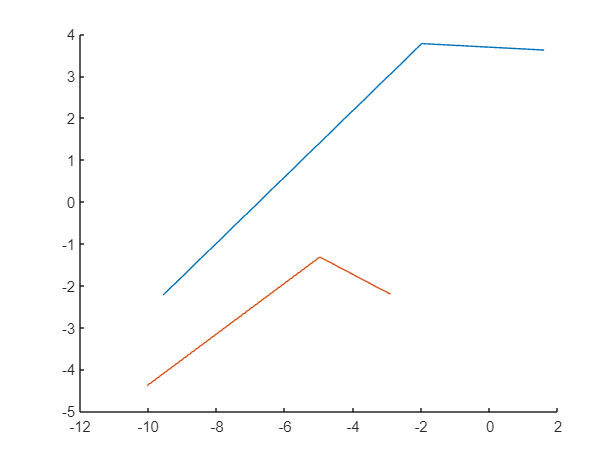

clf
hold on
plot3(X_b(1, :), X_b(2, :), X_b(3, :));
plot3(X(1, :), X(2, :), X(3, :));

%plot3(X_obvs_ens(1, :), X_obvs_ens(2, :), X_obvs_ens(3, :));

% Setup minimizer

%a = x0_b; b = X_obvs_ens; % Assign parameter values
f = @(x)var4(x,x0_b,X_obvs_ens,T_max,dt);

options = optimoptions('fminunc','Display','iter','Algorithm','trust-region','SpecifyObjectiveGradient',true);

[a,b] = f(x0)

a = 2.8943

b =     0.3690
    0.3000
   -0.4950


x = x0_b

x =    -9.5678
   -2.2230
   43.2644


for k = 1:5
    xb = x
    f = @(x)var4(x,xb,X_obvs_ens,T_max,dt);
    [x0_a,fval,exitflag,output] = fminunc(f,x,options)
    x = x0_a
end

xb =    -9.5678
   -2.2230
   43.2644



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0             754.66                           268                
     1             754.66        8.82109            268           1
     2            483.554        2.20527            184           0
     3             318.79        2.20527           91.8           1
     4            222.135        2.20527           30.5           1
     5            126.263        2.20527           24.4           1
     6            24.6824        4.41055           43.3           1
     7            3.64601        1.46709           4.39           1
     8              2.937       0.275271           2.01           1
     9            2.88549      0.0534443          0.433           1
    10            2.88549      0.0788052          0.433           1
    11            2.88321      0.0197013          0.295           0
    12            2.88321     0.00492533        

x0_a =   -10.0484
   -4.4103
   34.6886


fval = 2.8832

exitflag = 2

output = struct with fields:
         iterations: 19
          funcCount: 20
           stepsize: 3.0062e-07
       cgiterations: 10
      firstorderopt: 0.2952
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 3.006181e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0484
   -4.4103
   34.6886


xb =   -10.0484
   -4.4103
   34.6886



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0218058                         0.737                
     1          0.0147581        0.01754          0.193           1
     2          0.0121987      0.0125082         0.0826           1
     3          0.0121088     0.00288485         0.0316           1
     4          0.0119742     0.00340009         0.0313           1
     5          0.0117109     0.00227043         0.0145           1
     6          0.0117109    0.000884712         0.0145           1
     7          0.0117052    0.000221178        0.00834           0
     8          0.0116969    0.000442356        0.00665           1
     9          0.0116443    0.000884712        0.00657           1
    10          0.0116127    0.000323462        0.00206           1
    11          0.0116127    0.000245288        0.00206           1
    12          0.0116127    6.13219e-05        

x0_a =   -10.0310
   -4.4139
   34.6718


fval = 0.0116

exitflag = 3

output = struct with fields:
         iterations: 18
          funcCount: 19
           stepsize: 4.9629e-06
       cgiterations: 16
      firstorderopt: 2.5962e-05
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the final change in function value relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative objective function value is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0310
   -4.4139
   34.6718


xb =   -10.0310
   -4.4139
   34.6718



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0115056                       0.00708                
     1          0.0114746    0.000452562        0.00325           1
     2          0.0114723    0.000120019       0.000954           1
     3          0.0114723    0.000241561       0.000954           1
     4          0.0114723    6.03903e-05       0.000954           0
     5          0.0114723    1.50976e-05       0.000954           0
     6          0.0114723    3.77439e-06       0.000954           0
     7          0.0114723    9.43599e-07       0.000954           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.0305
   -4.4140
   34.6718


fval = 0.0115

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 9.4360e-07
       cgiterations: 3
      firstorderopt: 9.5386e-04
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 9.435987e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0305
   -4.4140
   34.6718


xb =   -10.0305
   -4.4140
   34.6718



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0114722                      0.000908                
     1          0.0114722    0.000199465       0.000908           1
     2          0.0114722    4.98662e-05       0.000908           0
     3          0.0114722    1.24666e-05       0.000908           0
     4          0.0114722    3.11664e-06       0.000908           0
     5          0.0114722     7.7916e-07       0.000908           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

x0_a =   -10.0305
   -4.4140
   34.6718


fval = 0.0115

exitflag = 2

output = struct with fields:
         iterations: 5
          funcCount: 6
           stepsize: 7.7916e-07
       cgiterations: 1
      firstorderopt: 9.0759e-04
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 7.791598e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0305
   -4.4140
   34.6718


xb =   -10.0305
   -4.4140
   34.6718



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0114722                      0.000908                
     1          0.0114722    0.000199465       0.000908           1
     2          0.0114722    4.98662e-05       0.000908           0
     3          0.0114722    1.24666e-05       0.000908           0
     4          0.0114722    3.11664e-06       0.000908           0
     5          0.0114722     7.7916e-07       0.000908           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

x0_a =   -10.0305
   -4.4140
   34.6718


fval = 0.0115

exitflag = 2

output = struct with fields:
         iterations: 5
          funcCount: 6
           stepsize: 7.7916e-07
       cgiterations: 1
      firstorderopt: 9.0759e-04
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 7.791598e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0305
   -4.4140
   34.6718


x0, x0_b, x0_a

x0 =   -10.0375
   -4.3845
   34.6514


x0_b =    -9.5678
   -2.2230
   43.2644


x0_a =   -10.0305
   -4.4140
   34.6718


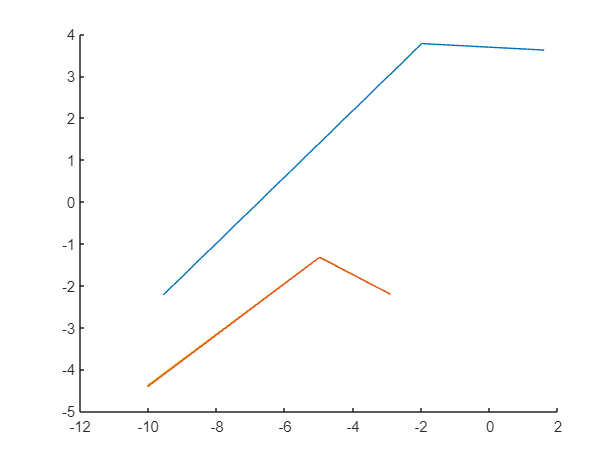

X_a = zeros(3,(round(T_max/dt)) + 1);
x = x0_a;
X_a(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X_a(:, i+1) = x;
end
clf
hold on
plot3(X_b(1, :), X_b(2, :), X_b(3, :));
plot3(X_a(1, :), X_a(2, :), X_a(3, :));
plot3(X(1, :), X(2, :), X(3, :));

Q2: